# Robotics2_4_2_2021

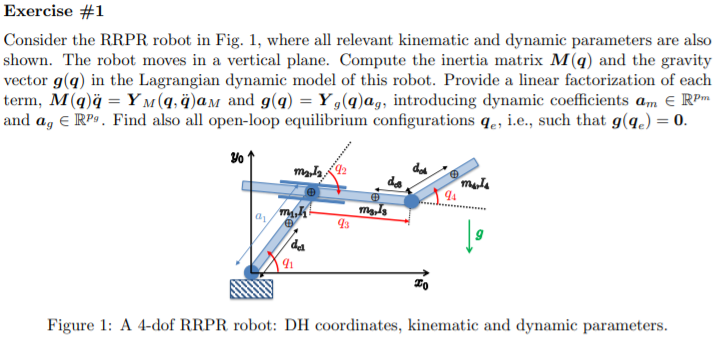

% clear all, clc, close all
% % This part is isolated from previous sectionclear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% % 1:revolute; 0:prismatic
% sigma = [1,1,0,1];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% 
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% % g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% % g=[0,-g0*sin(alpha_angle),0]';
% [Rx,Ry,Rz]=getEulerRotationMatrices([-alpha_angle,0,0])
% % g=[0,-g0*sin(alpha_angle),-g0*sin(alpha_angle)]'
% g=[0,-g0,0]'
% % g=vpa(expand(Rx*g))
% R2Robot=['rrpr';'xxxx';sigma]    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% 
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};!! pay attention to this
% % z.rcdefined=true;

% %% the following assumptions are due to the inexistence of l1 and dc1   
% dc(2)=0
% l(2)=0
% z.dc=dc;
% z.l=l;
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% 
% z.prismatic_CoM_method(3)=2;
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z);
% w
% vc
% T
% Ti
% M
% [C,cac,Csubs,S] = getCs(M,q,q_dot);
% cac

% vc(:,3)

% % qd
% 

% 
% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor);
% g_q_short
% U{:}

% %[All, dynamicParamsReturn, a]= getDynamicParameters([M,(S),diag(g_q)],q,[g],2)
% % [All, dynamicParamsReturn, a]= getDynamicParameters2([M,diag(g_q)],q,[l;g0]',2)

% 
% % [Msubs, dynamicParamsReturn, a]=getDynamicParameters2(M,q,l',2)%l')
% 

% [Msubs, dynamicParamsReturnM, aM]=getDynamicParameters2(M,q,l',2)
% [gsubs, dynamicParamsReturng, ag]=getDynamicParameters2(g_q,q,g0,2)

% 
% Msubs
% dynamicParamsReturnM
% gsubs
% dynamicParamsReturng
% % M

% % Msubs = All(:,1:4)
% % Ssubs = All(:,4:6)
% % gSubs = diag(All(:,5:8))
% % FSubs = All(:,10:12)

% % torqueSubs = Msubs*qdd + Ssubs*qd + gSubs +FSubs*qd
% a_orderM=aM([1,4,5,3,6,2])

% [YM,YM_short]=getLinearParametrization(Msubs*q_ddot,a_orderM)

% % torqueSubs = Msubs*qdd + Ssubs*qd + gSubs +FSubs*qd
% a_orderg=ag([2,3,1,4])

% [Yg,Yg_short]=getLinearParametrization(gsubs,a_orderg)